# A simple network

Single neurons, especially when considering their full biophysical and morphological details, can perform impressive calculations. It has long been known (e.g. [Shepherd and Brayton 1987](https://doi.org/10.1016/0306-4522(87)90329-0)) that logic operations can be performed in the dendrites of single neurons. The human brain, however, goes far beyond this with an estimated 86 billion neurons working together along with a comparable number of glia.

Here, we'll build a simple ring network where the $i^{\textrm{th}}$ neuron synapses onto the $i+1^{\textrm{th}}$ neuron, except for the last neuron, which synapses onto the first. We'll get our network to be active by stimulating the first cell once, and we'll watch as the cells spike in order.

## Get started

To get started we must create our NEURON object and load `stdrun.hoc`. Just to be safe, we'll also clear all MATLAB values and discard any existing sections.

clear;
n = neuron.launch();            % Initialize the NEURON session.
n.reset_sections();             % Reset topology.
n.load_file("stdrun.hoc");      % load the standard run control

## The model

We'll need a bunch of neurons, say this many:

NUM_NEURONS = 10;

For more complicated cells (e.g. with morphology), we'll often want to create each cell as a class instance, but here, we can just create a list of cells that area all single sections:

cells = arrayfun(@(i){n.Section("cell"+i)}, 1:NUM_NEURONS);

To see what `cells` looks like, we can check:

length(cells)

ans = 10

and

cells{3}

ans =   Section with properties:

     mech_list: ["morphology"    "capacitance"    "pas"    "extracellular"    "fastpas"    "na_ion"    "k_ion"    "hh"]
    range_list: ["v"    "i_membrane_"    "diam"    "cm"    "i_cap"    "g_pas"    "e_pas"    "i_pas"    "xraxial"    "xg"    "xc"    "e_extracellular"    "i_membrane"    "vext"    "g_fastpas"    "e_fastpas"    "ena"    "nai"    "nao"    "ina"    …    ]
        length: 100
          nseg: 1
          name: "cell3"


 Each cell will be defined similarly, with the same size soma and the same Hodgkin-Huxley dynamics:

for i=1:NUM_NEURONS
    my_cell=cells{i};
    my_cell.length = 5;  % um
    my_cell.set_diameter(5);
    my_cell.insert("hh");
end

Now lets create a synapse (more accurately, a postsynaptic mechanism) on each cell using an `ExpSyn`, a simple synapse model whose conductance decays exponentially over time. The synapses will all have the same reversal potential and time course:

syns = cell(1, NUM_NEURONS);  % create empty cell array
for i=1:NUM_NEURONS
    syn = n.ExpSyn(cells{i}(0.5));
    syn.e = 0;
    syn.tau = 0.1;
    syns{i} = syn;
end

Each of these postsynaptic mechanisms need to be connected to a presynaptic mechanism. In NEURON, this is done with a `NetCon`. We'll end with a cell array `ncs` of `NetCon` objects:

ncs = cell(1, NUM_NEURONS);  % create empty cell array
for i=1:NUM_NEURONS
    if i == numel(cells)
        post_syn = syns{1};
    else
        post_syn = syns{i+1};
    end
    cells{i}.push();  % must do this and the pop in MATLAB; in Python, just say sec=
    nc = n.NetCon(cells{i}(0.5).ref("v"), post_syn);
    n.pop_section();
    nc.weight = 1;  % this is a strong weight, chosen so the cell fires from one input
    nc.delay = 1;   % ms
    ncs{i} = nc;
end

## Stimulating our model

To get our network to do anything, it needs some input from outside the network. We'll do this with a `NetStim`. Here, we'll just use a single, strong external stimulus at time 2 ms, but `NetStim` can also be used to generate regular stimuli or random stimuli according to a Poisson process.

ns = n.NetStim();
ns.start = 2;  % ms
ns.number = 1;

And now we need a `NetCon` connecting this stimulus to the first cell's post-synaptic mechanism:

stim_nc = n.NetCon(ns, syns{1});
stim_nc.weight = 1;
stim_nc.delay = 0;  % no point adding delay here; let's just have it received at the chosen time

## Recording our model

For network models, we often don't need to record the exact time series of membrane potential (this can often be reconstructed if needed without rerunning the whole model); instead, it often suffices to record the times each cell spikes.

We'll do this by having the $i^{\textrm{th}}$ `NetCon` (which is attached to the $i^{\textrm{th}}$ cell), record the times it detects a spike to a `Vector`, and thus we'll end up with a cell array of `Vector` objects, one for each cell. (In larger models using classes, consider doing this inside the cell class itself).

spike_times = cell(1, numel(cells));  % create empty cell array for vectors
for i=1:NUM_NEURONS
    nc = ncs{i};
    spike_vec = n.Vector();
    nc.record(spike_vec);
    spike_times{i} = spike_vec;
end

## Run the model

n.finitialize(-65);
n.continuerun(100);

## Plot the spikes

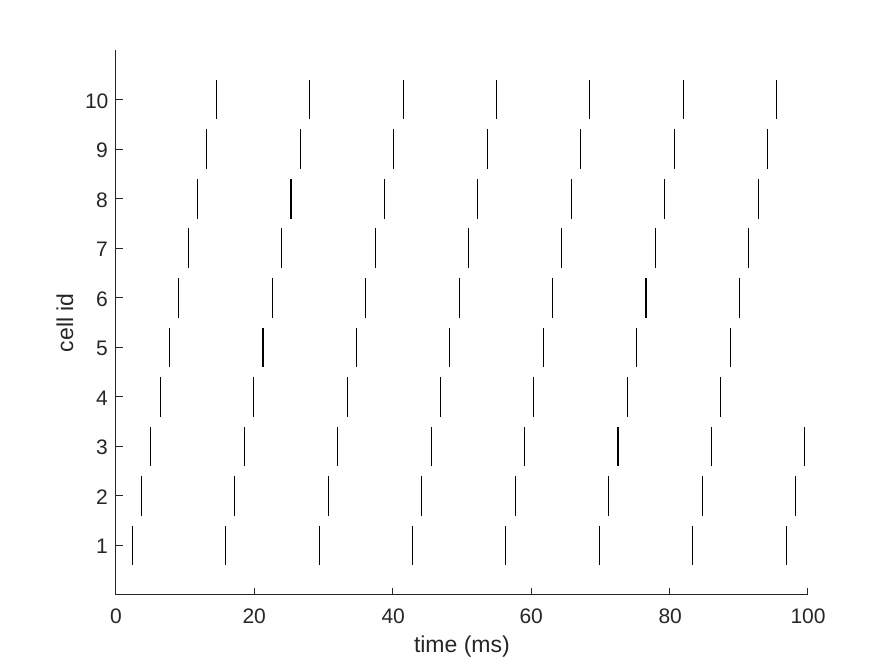

for i = 1:NUM_NEURONS
    ylo = i - 0.4;
    yhi = i + 0.4;
    times = double(spike_times{i});
    for time=times
        plot([time time], [ylo yhi], "k");
        hold on;
    end
end
ylabel("cell id");
xlabel("time (ms)");
yticks(1:NUM_NEURONS);
ylim([0, NUM_NEURONS + 1]);
box off;
hold off;